# Practice Curvilinear Regression: Linearizable Functions

[⇦ Curvilinear Regression](matlab:open('./CurvilinearRegressionSoln.mlx'))

After learning the principles of [curvilinear regression](matlab:open('./CurvilinearRegressionSoln.mlx')), this exercise allows you to demonstrate your understanding through practical applications in MATLAB.

[image: rechargeable battery]

Learn and apply the curvilinear regression workflow for linearizable functions, below. 

**Before you get started:**

This live script is intended to be used with the code visible and output inline. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output Inline** using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will build some familiarity with MATLAB as concepts and commands are introduced together. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections, and they will generate errors if run out of order.

The    and  icons refer to two different types of interactive activities that you will find in this script. The   usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

To run the code, you can click the 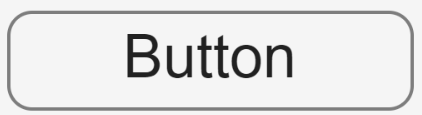 **Button** provided, or you can use [image: Run Section icon] **Run Section** or [image: Run and Advance icon] **Run and Advance** in the Live Editor tab of the tool strip, or the equivalent keyboard commands of Ctrl-Enter to run a section or Ctrl-Shift-Enter to run and advance.

## Notes About this Script  

We will use [Name-Value Arguments](https://www.mathworks.com/help/matlab/matlab_prog/validate-name-value-arguments.html?s_tid=srchtitle_support_results_1_Name-Value%2520arguments) throughout this script such as `DisplayName="Data"`, `Location="best"`. In addition, rather than manually labeling entries on legends, we will use the following format: `legend("show",Location="best")`. In [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), you can practice with Name-Value Arguments in the [Plots](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted#module=9) section. We will also use [dot notation](https://www.mathworks.com/help/matlab/creating_plots/access-and-modify-property-values.html) to access properties of tables. 

In the [Explore Data with MATLAB Plots](https://matlabacademy.mathworks.com/details/explore-data-with-matlab-plots/otmledp) in the [Visualize Vectors](https://matlabacademy.mathworks.com/details/explore-data-with-matlab-plots/otmledp#module=2) section, you can learn more about Name-Value Arguments.

Learn more about dot notation:

-  [Access and Modify Plot Properties ](https://matlabacademy.mathworks.com/details/how-matlab-graphics-work/otmlhgw#module=3)in the Self-Paced Online Course, [How MATLAB Graphics Work](https://matlabacademy.mathworks.com/details/how-matlab-graphics-work/otmlhgw)

- The documentation page [dot notation](https://www.mathworks.com/help/matlab/creating_plots/access-and-modify-property-values.html)

## Fit Linearizable Nonlinear Data with Linear Regression Model

In the next set of exercises, we will linearize the different types of functions and find the regression model of the linearized fit. Recall from [CurvilinearRegression](matlab:open('./CurvilinearRegressionSoln.mlx')), we used the following transformations to linearize various functions. We also learned that exponential fits appear linear on **semilogy** plots while power data appear linear on **loglog** plots in the [Linearizable Nonlinear Regression](matlab:open('./CurvilinearRegressionSoln.mlx')) section. 

### Generate Data

  **Try**. Click **Generate Data**.

 
TP = GenPowData; % Use function to generate data
xPl = TP.xPl; % Extract the input variable from the table
yPl = TP.yPl; % Extract the response variable from the table
head(TP) % View top rows of table data and the column labels

### Plot Data

  **Try**. Select an axis from the **dropdown menu** below, and then click **Plot Data** to view the data plotted on different axes.

AX = "x-y"; % Use this dropdown menu to select an axis on which to plot the data
plotDataByAxis(AX,xPl,yPl)
  % Click this button to plot the data

### Determine the Appropriate Linearization Strategy

 **Exercise 1.** Based on the way the data fits on the various axes, standard x-y, semilogy, and log-log, which type of function best describes the data? Select and answer from the **dropdown menu** and then click **Check Answer**.

Answer = "Saturation"; % Select an answer from this dropdown menu
checkAnswer(1,Answer)
  % Click this button to check your answer

### Linearize Data

  **Try**. We linearize the data using the appropriate linearization strategy for the data below. Click **Linearize Data**, to linearize data.

% Ensure logx and logy are real numbers and remove non-positive values
valid = xPl > 0 & yPl > 0 & isfinite(xPl) & isfinite(yPl);

% Additionally remove any negative or zero entries explicitly (defensive)
valid = valid & (xPl > 0) & (yPl > 0);

xP1 = xPl(valid);
yP1 = yPl(valid);
plotDataByAxis("log-log",xP1,yP1)
 

### Perform Linear Regression of Linearized Model

In [TryRegression](file:matlab:open('matlab:open('matlab:open('matlab:open(''./TryRegressionSoln.mlx'')), we explored how to calculate regression line coefficients in MATLAB and plot them alongside a scatter plot. The great part about linearizing an equation is that it turns a traditionally difficult, nonlinear problem into something we can handle with the same simple linear regression techniques we already know. It’s like unlocking a shortcut to analyze complex data!

  **Try**. We can use the [`fitlm`](https://www.mathworks.com/help/stats/fitlm.html) function in MATLAB to calculate the coefficients for a regression line, and display the scatter plot with the regression line and the 95% confidence interval. Click **Perform Linear Regression** to perform linear regression on the linearized model.

logx = log10(xP1);
logy = log10(yP1);
mdl = fitlm(logx,logy); % Fit linear model to linearized data
plot(mdl) % Plot the fitted regression line with diagnostics
xlabel("log(x)")
ylabel("log(y)")
title("Linearized Power Fit")
legend("show",Location="best")
hold on % Retain current plot on axes
 

### Use Linear Regression Model to Predict One Response

  **Try**. We use the [`predict`](https://www.mathworks.com/help/stats/linearmodel.predict.html?s_tid=srchtitle_support_results_3_predict#d126e1014929) function in MATLAB to predict a response for $\text{log}(x) = 0.67$ with the linearized regression model

% Predict the responses of the linear regression model
logyPred = predict(mdl,0.67); % Use the fitted model to predict y values for the input x Try.

  **Try**. In addition, we overlay a [`scatter`](https://www.mathworks.com/help/matlab/ref/scatter.html?s_tid=srchtitle_support_results_1_scatter) plot of the predicted values on the response plot above, using filled diamond markers with a marker size of 60 points. Click **Plot Predicted Value** to plot the predicted value for $\text{log}x=0.67$.

% Enter your code here.
% Plot original data and predictions
scatter(0.67,logyPred,60,"filled","d",DisplayName="Prediction for 0.67",SeriesIndex="none")
legend("show",Location="best") % Add a legend to the plot
title("Linearized Power Data + Prediction")
hold off % Release all plots from the axes
 

 **Exercise 2.** Recall that with our linearized data, we applied a log10 transform to both x and y. So for $\text{log}x=0.67$, we know that $x=10^{0.67}= 4.68$. Calculate the value for$yPred$ below.

% Enter your code here.
yPred = 10^logyPred

##  **Application 1. Battery Lifetime Decay Problem**

A battery undergoes charging and discharging over time. Its **state-of-health (SOH)** decreases as internal resistance changes. You are given data for $SOH$ versus time ($t$) in the file `BatterySOH.mat`. Fit a regression model to describe SOH degradation over time $t$. Briefly interpret what the slope or trend means for battery aging.

### Load Battery Lifetime Data

 **Exercise 3a.** Load battery data from `BatterySOH.mat` into a table `TBat` with columns `t` and `SOH` by **clicking** the button below.

% Load battery data and plot data using a scatter plot with correct labels
load BatterySOH.mat t SOH
TBat = table(t(:),SOH(:),VariableNames={'t','SOH'}); % Create a table of the data with variable names
head(TBat) % View top rows and columns of the table
 

### Plot Data

 **Exercise 3b.** Create a [`scatter`](https://www.mathworks.com/help/matlab/ref/scatter.html?s_tid=srchtitle_support_results_1_scatter) plot of the battery data of SOH vs. `time` in the code block below. 

% Enter your code here.
scatter(t,SOH,"filled",DisplayName="Data")
xlabel("time (hours)")
ylabel("State of Health (SOH)(%)")
box on

### Linearize Data

 **Exercise 3c.** Linearize the data using the appropriate linearization strategy.

% Enter your code here.
% Linearize SOH data
SOHExp = log(SOH); % Transform SOH using natural logarithm

### Run the Linear Regression and Plot the Line

 **Exercise 3d.** Use [`fitlm`](https://www.mathworks.com/help/stats/fitlm.html) to find the regression model.

% Enter your code here.
% Fit linear regression model to the transformed data
mdlSOH = fitlm(t,SOHExp);

 **Exercise 3e.** Enter code to the [`plot`](https://www.mathworks.com/help/matlab/ref/plot.html?s_tid=srchtitle_support_results_1_plot) function in MATLAB to plot the predicted response of the linear regression model. 

  **Pro-tip**. You will want to use the [hold on](https://www.mathworks.com/help/releases/R2026a/matlab/ref/hold.html?s_tid=srchtitle_site_search_1_hold%2520on&searchPort=60283#d126e778569) command to retain this plot for the next exercise.

% Enter your code here.
% Plot the regression model
plot(mdlSOH);
xlabel("time")
ylabel("ln(SOH)")
title("Linearized State of Health (SOH) Data")
hold on % Retain current plot

### Use Linearized Regression Model to Predict One Response

 **Exercise 3f.** Use the [`predict`](https://www.mathworks.com/help/stats/linearmodel.predict.html?s_tid=srchtitle_support_results_3_predict#d126e1014929) function in MATLAB to predict the $\text{ln}(SOH)$ for $t = 5.3$. 

% Enter your code here.
% Predict response for t = 5.3
predictedSOHt53 = predict(mdlSOH,5.3)

 **Exercise 3g.** Create a scatter plot to plot the predicted $\text{ln}SOH$ at $time = 5.3$ on the current figure of the linearized regression model and label it using a filled diamond marker for the predicted point.

  **Pro-tip**. Don't forget to release the scatter plot from the axes with [`hold off`](https://www.mathworks.com/help/releases/R2026a/matlab/ref/hold.html?s_tid=srchtitle_site_search_1_hold%2520on&searchPort=60283#d126e778590)`.`

% Enter your code here.
scatter(5.3,predictedSOHt53,60,"d","filled",DisplayName="Predicted SOH at t=5.3",SeriesIndex="none")
hold off % Release the current figure so subsequent plots do not overlay on this plot

### Convert Predictions to Nonlinear Form and Plot SOH

In the previous section, we calculated the predicted value of $\text{ln}SOH$ for $t=5.3$; however, to determine the battery state of health at that time, we must perform the inverse transform from the previous section.

  **Exercise 3h.** Transform the predicted value back to its nonlinear form to find the $SOH$ of the battery at $t=5.3$. Then add the predicted value to a scatter plot of SOH vs. time on a standard x-y axis.

% Enter your code here.
SOHt53 = exp(predictedSOHt53); % Calculate predicted value
% Plot the predicted value on the standard x-y axis
scatter(t,SOH,"filled",DisplayName="Data",MarkerFaceColor=[0.9290 0.6940 0.1250])
hold on
scatter(predictedSOHt53,SOHt53,60,"d","filled",DisplayName="Predicted Value",MarkerFaceColor=[0.1840 0.7450 0.9370])
xlabel("time (hours)")
ylabel("SOH (%)")
legend("show",Location="best")
box on
hold off

##  **Application 2.** Modeling Motor Heat Rise and Thermal Saturation

A motor generates heat during operation, and its case temperature rises quickly at first, then levels off as heat loss balances heat generation. This creates a **saturation curve**. The code below will generate a table, `TSat` with variable `time` and `Temp.`

 **Exercise 4a.** Click **Load Data.**

 
TSat = GenSatB; % Use function to generate data
time = TSat.t; % Extract the input variable from the table
Temp = TSat.Temp; % Extract the response variable from the table
head(TSat) % View top rows of table data and the column labels

### Plot Data

Plot temperature(Temp) vs. time from the provided data or simulation.

 **Exercise 4b.** Make a scatter plot of the saturation curve data.

% Enter your code here.
% Make a scatter plot of the saturation curve data
scatter(time,Temp,"filled",MarkerFaceAlpha=0.6,SeriesIndex=3)
xlabel("time")
ylabel("Saturation Response (Temperature)")
title("Saturation Curve Dataset")
box on

### Determine the Appropriate Linearization Strategy

 **Exercise 4c.** Select axes from the **dropdown menu** to find the linear graph. Then click **Validate Answer**.

AX2 = "x-y";
plotDataByAxis(AX2,time,Temp)
checkAnswer(2,AX2)
 

### Linearize Data

 **Exercise 4d.** Use the appropriate linearization strategy for the saturation curve data.

% Enter your code here.
% Linearize the saturation data using 1/t and 1/Time
Invtime = 1 ./ time; % Inverse of predictor values
InvTemp = 1 ./ Temp; % Inverse of response values

% Remove any infinite values from Invtime and InvTemp
isFinitePair = isfinite(Invtime) & isfinite(InvTemp);
Invtime = Invtime(isFinitePair);
InvTemp = InvTemp(isFinitePair);

### Perform Linear Regression of Linearized Data

 **Exercise 4e.** Use [`fitlm`](https://www.mathworks.com/help/stats/fitlm.html) to find the regression model for the variable `mdlSat` and plot the linear regression.

% Enter your code here.
% Use fitlm to find the regression model
mdlSat = fitlm(Invtime,InvTemp);
plot(mdlSat)
xlabel("1/time")
ylabel("1/Temp")
title("Linearized Saturation Curve Data (1/time vs 1/Temp)")

### Use Linearized Regression Model to Predict One Response

 **Exercise 4f.** We can use the [`predict`](https://www.mathworks.com/help/stats/linearmodel.predict.html?s_tid=srchtitle_support_results_3_predict#d126e1014929) function in MATLAB to predict the temperature at $time= 5$. After making a prediction, be sure to convert it back to temperature by applying the inverse of the transformation used to linearize the model.

% Enter your code here.
% Use the predict function to predict the temperature at time = 5
invTatt5 = predict(mdlSat,1/5); % predict 1/Temp at 1/time = 1/5
% Predict inverse-temperature for time = 5 using mdlSat (model is InvTemp vs Invtime)
predictedSat = 1 / invTatt5; % convert back to temperature Temp

### Used Linearized Regression Model to Predict Multiple Values

 **Exercise 4g.** We can use the [`predict`](https://www.mathworks.com/help/stats/linearmodel.predict.html?s_tid=srchtitle_support_results_3_predict#d126e1014929) function in MATLAB to predict the temperatures at $time= 2.7,3.9, \text{ and } 8.4$. After making the predictions, be sure to convert them back to temperature by applying the inverse of the transformation used to linearize the model.

% Enter your code here.
% Predict inverse-temperature for given t values and convert back to temperature
tList = [2.7;3.9;8.4];
% mdlSat models InvTemp vs Invtime, so provide Invtime = 1./tQuery to predict InvTemp
invTpred = predict(mdlSat,1./tList);
% Convert predicted 1/T back to T
Tpred = 1 ./ invTpred;
% Display results as table
disp(table(tList,Tpred,VariableNames={'t','PredictedTemp'}))

## Linearization Strategies

(↑ Return to Exercise 3c)

(↑ Return to Exercise 4d)

## Further Exploration

You can use the [Battery State of Health Estimation](https://www.mathworks.com/help/simscape-battery/ug/battery-state-of-health-estimation.html) example to generate new data to perform curvilinear regression.

[⇦ Return to Curvilinear Regression](matlab:open('./CurvilinearRegressionSoln.mlx'))

## Local Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline** using the icon   at the top right of the Live Editor pane.

function TSat = GenSatB
% Generate a saturation curve dataset and return as a table with variables t and Temp
time = linspace(0,10,100)'; % predictor values
maxResponse = 5; % maximum response value
saturationConstant = 2; % saturation constant
noiseStdSat = 0.05; % noise level for saturation data
Temp = maxResponse * (time ./ (saturationConstant + time)) + noiseStdSat * randn(size(time)); % saturation curve with noise
TSat = table(time,Temp,VariableNames={'t','Temp'});
end

function TP = GenPowData()
% GenPowData Generate synthetic power-law data suitable for  log-log plots

rng shuffle

% Predictor values (log-spaced is often better for power laws)
xPl = logspace(-1,1,100)';

% True parameters
aTrue = 3.5;
bTrue = 1.8;
sigma = 0.15;  % log-space noise level

% Generate multiplicative (log-normal) noise
noiseFactor = exp(sigma * randn(size(xPl)));

% Power-law with multiplicative noise
yPl = aTrue .* (xPl.^bTrue) .* noiseFactor;

TP = table(xPl,yPl);
end

function plotDataByAxis(AX,xPl,yPl)

switch AX
    case "Select"
        warning("Select a valid option.")
        return

    case "x-y"
        scatter(xPl,yPl,"filled",DisplayName="Data",SeriesIndex=3)
        xlabel("x")
        ylabel("y")
        title("Standard x-y Plot")

    case "semilogy"
        semilogy(xPl,yPl,"o",MarkerFaceColor=[0.9290 0.6940 0.1250],SeriesIndex=3,DisplayName="Data")
        xlabel("x")
        ylabel('$\ln(y)$',"Interpreter","latex")
        title("Semilog Plot for Exponential")

        %Make axes natural log
        yl = ylim;
        k = floor(log(yl(1))):ceil(log(yl(2)));
        yticks(exp(k));
        yticklabels(compose("e^{%d}",k));

    case "log-log"
        loglog(xPl,yPl,"o",MarkerFaceColor=[0.9290 0.6940 0.1250],SeriesIndex=3,DisplayName="Data")
        xlabel("$x$ (log scale)",Interpreter="latex")
        ylabel("$y$ (log scale)",Interpreter="latex")
        title("Loglog Plot for Power Law")
    case "saturation"
        scatter(1./xPl,1./yPl,"filled",SeriesIndex=3,DisplayName="Data")
        xlabel("$1/x$",Interpreter="latex")
        ylabel("$1/y$",Interpreter="latex")
        title("Saturation Plot")
    case "sigmoidal(S-Curve)"
        scatter(xPl,log(1./yPl),"filled",SeriesIndex=3,DisplayName="Data")
        xlabel("$x$",Interpreter="latex")
        ylabel("$ln(y/1-y)$",Interpreter="latex")
        title("Saturation Plot")
end

box on
grid on
legend("show","Location","best")
end

function checkAnswer(ExID,Answer)
%CHECKANSWER Validate answer for exercise ExID and provide tailored hints.
% ExID: numeric or string identifying the exercise (1 or 2 supported)
% Answer: user's answer as string or char

% Normalize inputs
if isnumeric(ExID)
    exID = ExID;
else
    exID = str2double(string(ExID));
    if isnan(exID)
        exID = -1;
    end
end
ansStr = string(Answer);

% Define correct answers and hints for supported exercises
switch exID
    case 1
        correct = "Saturation";
        hintMsg = "Hint: For Exercise 1, which plot shows linear behaviors?";
    case 2
        correct = "x-y";
        hintMsg = "Hint: For Exercise 4b, which plot shows linear behaviors?";
    otherwise
        warning("Unsupported ExID. Provide ExID=1 or ExID=2.");
        return
end

% Validate answer
if strcmpi(ansStr,"Select")
    warning("Select a valid answer.");
    return
end

if ansStr == correct
    disp("You are correct.")
else
    disp(hintMsg)
end
end